# FMCW Radar Lab: Target Tracking

This lab combines a number of concepts to demonstrate a tracking radar. In this script, we beamform to multiple directions and perform the CFAR algorithm to generate detections with estimates of range, speed, and direction of arrival. We then use this information to generate tracks to follow targets in the field of view.

## System Setup

Before going through the lab, we prepare the workspace by clearing variables, closing figures, suppressing warnings.

clear;
close all;
warning('off','MATLAB:system:ObsoleteSystemObjectMixin');

For this lab, we use many of the same parameters that were used in previous labs.

% Setup Phaser
fc = 10.42e9;
prf = 1000;
nPulses = 64;
fs = 1e6;
rampbandwidth = 500e6;
[rx,tx,bf,bf_TDD] = setupLabRadar(fc,prf,nPulses,fs,rampbandwidth);

% Setup the array model for steering
lambda = freq2wavelen(10.7e9);
spacing = lambda/2;
array = phased.ULA(NumElements=2,ElementSpacing=spacing);
elementPosition = array.getElementPosition();

Load the calibration weights which are required for steering the antenna.

load('CalibrationWeights.mat','calibrationweights');

## Signal Processing Setup

Setup the range-Doppler processing object.

tSweep = double(bf.FrequencyDeviationTime)/1e6;
sweepSlope = rampbandwidth/tSweep;
rd = phased.RangeDopplerResponse(DopplerOutput="Speed",...
    OperatingFrequency=fc,SampleRate=fs,RangeMethod="FFT",...
    SweepSlope=sweepSlope,PRFSource="Property",PRF=prf);

Setup the CFAR detector.

pfa = 1e-4;
guard = 2;
train = 3;
cfar = phased.CFARDetector2D(ProbabilityFalseAlarm=pfa,GuardBandSize=[guard guard],TrainingBandSize=[train train]);

Setup the beamscan estimator.

bscan = phased.MVDREstimator2D(SensorArray=array,OperatingFrequency=fc);

Use an MTI filter.

mti = [1 -2 1];
nfilt = length(mti);

We look for moving targets out to 10 meters.

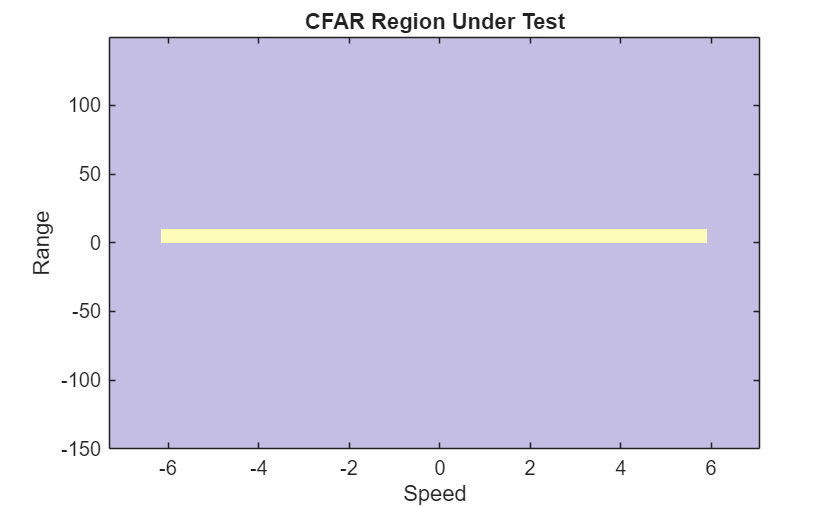

minRange = 0.1;
maxRange = 10;
vmin = 0;
vmax = inf;
[cut,speed,range] = getCFARCUT(minRange,maxRange,vmin,vmax,guard,train,prf,nPulses-nfilt+1,fc,fs,tSweep,rampbandwidth);
plotCFARRegion(cut,range,speed);

The yellow regions are the regions of the range-Doppler space that we will be testing for detections.

We setup some properties for detection definition. The measurement parameters define the coordinates. The measurement noise is derived from the expected azimuth error, the range resolution, and the velocity resolution.

detParams = struct(Frame="spherical",HasElevation=false);
azErr = 20^2;
rangeErr = (range(2)-range(1))^2;
speedErr = (speed(2)-speed(1))^2;
measNoise = diag([azErr;rangeErr;speedErr]);

A JPDA tracker with a motion model based on human walking is used.

trackGenerator = TrackGenerator();

## Data Collection

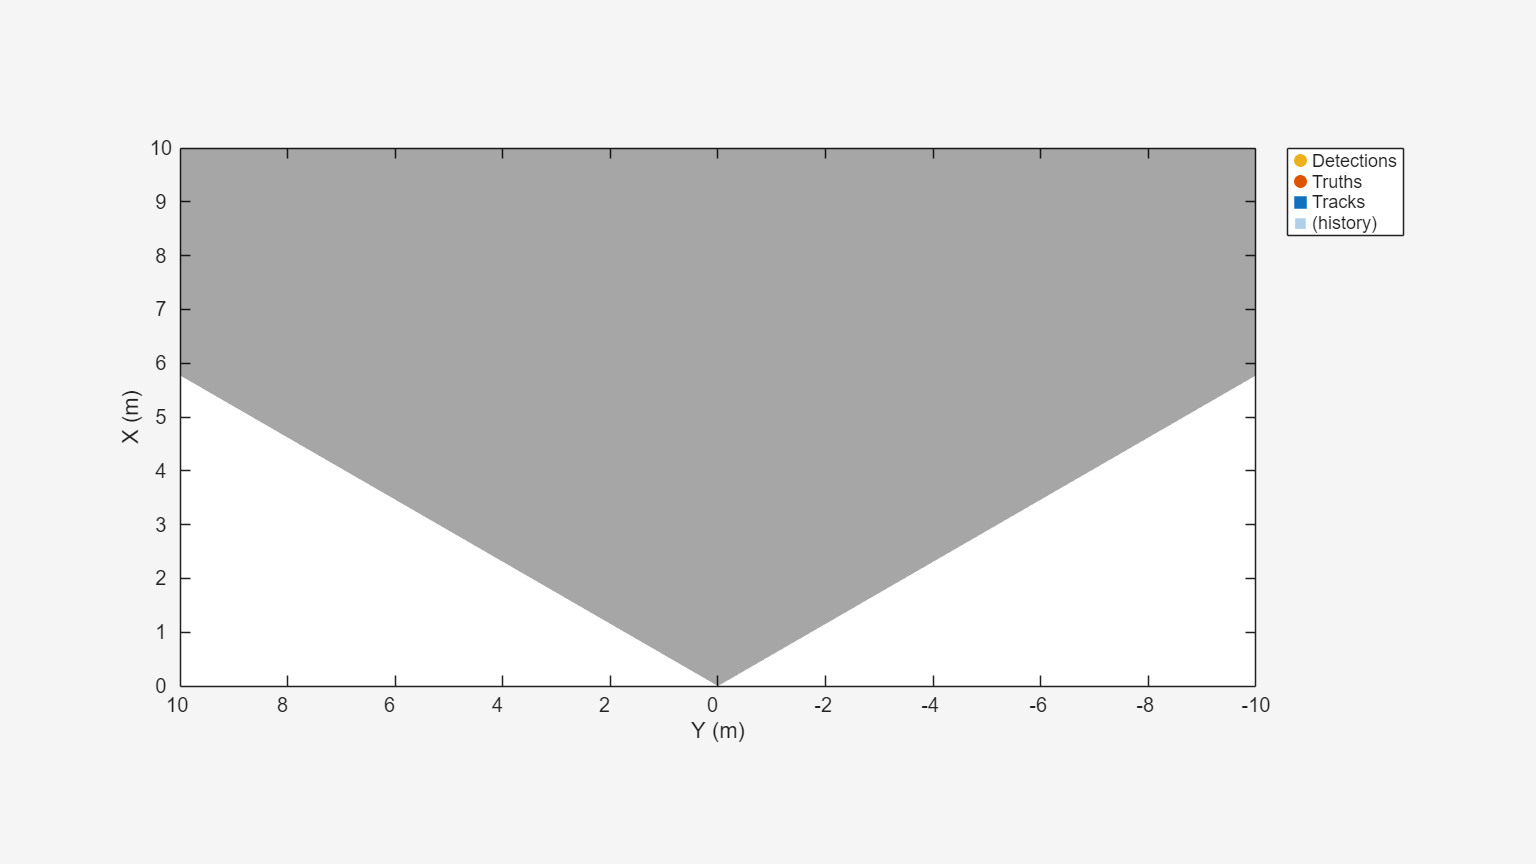

% Run time in seconds
tCapture = 600;

% Setup the steering angles
steerang = 0;
nang = length(steerang);

% Create a display object
display = HelperRadarTrackingDisplay('XLimits',[0 maxRange],...
    'YLimits',[-maxRange maxRange],...
    'MaxRange',30,...
    'CameraReferenceLines',zeros(2,0),...
    'RadarReferenceLines',zeros(2,0),...
    'PlotReferenceImage',0);
display(objectDetection.empty(0,1),objectTrack.empty(0,1),[]);

% Initialize the data capture
captureTransmitWaveform(rx,tx,bf);

% Save the number of range and Doppler cells
nrange = length(range);
nspeed = length(speed);

tseed = tic;
t = toc(tseed);
while t < tCapture
    % Update time
    t = toc(tseed);

    % Steer the analog beamformers
    analogsteer = analogWeightsCalAdjustment([0 1;0 0;0 0;1 0],calibrationweights.AnalogWeights);
    setAnalogBfWeights(bf,analogsteer);

    % Trigger burst pulse
    bf.Burst=false;bf.Burst=true;bf.Burst=false;

    % Capture pulse period
    data = rx();

    % Get data matrix for each channel
    datapulse1 = arrangeSinglePulseData(data(:,1),rx,bf,bf_TDD);
    datapulse2 = arrangeSinglePulseData(data(:,2),rx,bf,bf_TDD);

    % Apply MTI filter to each channel, remove pulses in transient region
    datapulse1 = filter(mti,1,datapulse1,[],2);
    datapulse1 = datapulse1(:,nfilt:end);
    datapulse2 = filter(mti,1,datapulse2,[],2);
    datapulse2 = datapulse2(:,nfilt:end);

    % RD response
    [rddata1,~,~] = step(rd,datapulse1);
    [rddata2,range,speed] = step(rd,datapulse2);
    
    % Get index of detections for each pulse
    [d1] = cfar(abs(rddata1).^2,cut);
    [d2] = cfar(abs(rddata2).^2,cut);
    detidx1 = cut(:,d1');
    detidx2 = cut(:,d2');
    detidx = [detidx1 detidx2];

    % Init detections
    ndets = size(detidx,2);
    detections = cell(1,ndets);
    
    % Get the range, speed, angle, for the detections
    for idet = 1:ndets
        ridx = detidx(1,idet);
        sidx = detidx(2,idet);
        drange = range(ridx);
        dspeed = speed(sidx);
        dpoint = [rddata2(ridx,sidx) rddata1(ridx,sidx)];
        calweights = loadCalibrationWeights().DigitalWeights;
        outdata = dpoint .* conj(calweights).';
        bout = bscan(dpoint);
        [~,angidx] = max(bout);
        doa = bscan.ScanAngles(angidx);
        measurement = [doa;drange;dspeed];
        detections{idet} = objectDetection(t,measurement,MeasurementNoise=measNoise,MeasurementParameters=detParams);
    end

    % Cluster detections
    if isempty(detections)
        clusters = zeros(0,1,'uint32');
    else
        clusters = partitionDetections(detections,3,1,'Algorithm','DBSCAN');
    end
    
    % Centroid estimation
    clusteredDets = mergeDetections(detections,clusters);
    
    % Create tracks from detections
    tracks = trackGenerator.track(clusteredDets,t);

    % Display results
    display(detections,tracks,[]);
end

Unrecognized method, property, or field 'ScanAngles' for class 'phased.MVDREstimator2D'.


% Disable TDD Trigger
cleanupAntenna(rx,tx,bf,bf_TDD);

function ax = plotCFARRegion(cut,range,speed)
    % Plot the CFAR region that will be tested for detections
    
    % Create axes to plot region
    ax = axes(figure);
    
    % Plot the cfar region image
    cfartest = zeros(length(range),length(speed));
    ncut = size(cut,2);
    for iCut = 1:ncut
        cfartest(cut(1,iCut),cut(2,iCut)) = 1;
    end
    imagesc(ax,speed,range,cfartest,'AlphaData',0.3);
    
    % Update axes
    title(ax,'CFAR Region Under Test');
    xlabel(ax,'Speed');
    ylabel(ax,'Range');
    ax.YDir = "Normal";
end